# 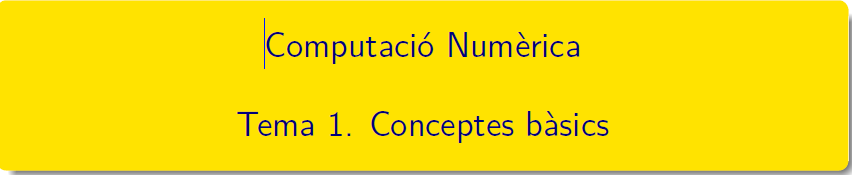

====================================================================================

# Tema 1 - Conceptes Bàsics

## Algorismes

### Evitar la propagació d'errors

Per tal de reduir o evitar la propagació dels errors es recomana, minimitzar el nombre d’operacions, reordenar les operacions i replantejar el problema en altres termes.

#### Equació de segon grau

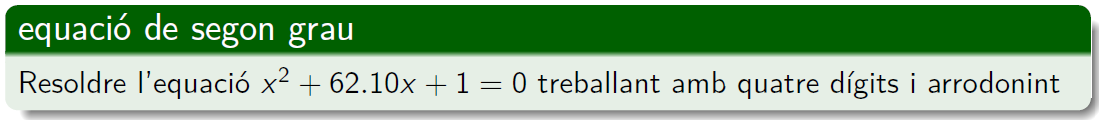

clearvars, format, n = 4;
fprintf('fent ús de roots'), arrels = roots([1 62.10 1])'

fent ús de roots

arrels =   -62.0839   -0.0161


Es calcula amb la fórmula $\frac{-b\pm\sqrt{b^2-4ac}}{2a}=-31.05\pm\sqrt{31.05^2-1}$

b = 31.05;
y = round(sqrt(b^2 - 1),n,'significant');
x1 = round(-b - y,n,'significant')

x1 = -62.0800

x2 = round(-b + y,n,'significant')      % al fer -b + sqrt(...) perdo info

x2 = -0.0200

Es calcula amb la fórmula $x_1=-31.05-\sqrt{31.05^2-1},\quad  x_3 = 1/x_1$

x1

x1 = -62.0800

x3 = round(1/x1,n,'significant')       % per no perdre info

x3 = -0.0161

Xifres decimales correctes

ve1 = arrels(1); ve2 = arrels(2);
ea_x1 = abs(x1-ve1);
ea_x2 = abs(x2-ve2);
ea_x3 = abs(x3-ve2);
er_x1 = (ea_x1/abs(ve1)) * 100;
er_x2 = (ea_x2/abs(ve2)) * 100;
er_x3 = (ea_x3/abs(ve2)) * 100;
R = [arrels ve2; x1 x2 x3; ea_x1 ea_x2 ea_x3; er_x1 er_x2 er_x3]';
T = array2table(R,...
    'VariableNames',{'arrel','arrel_4_digits','error absolut','error relatiu %'},"RowNames",{'x_1','x_2','x_3'}); disp(T)

             arrel      arrel_4_digits    error absolut    error relatiu %
           _________    ______________    _____________    _______________

    x_1      -62.084         -62.08         0.0038928         0.0062702   
    x_2    -0.016107          -0.02         0.0038928            24.168   
    x_3    -0.016107       -0.01611        2.7626e-06          0.017151   



#### Regla de Horner

Per avaluar expressions polinomials 

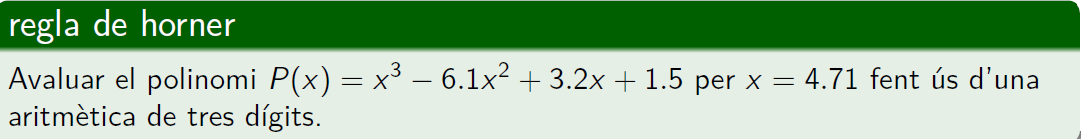

- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$

n = 3;
P = @(x)((x-6.1)*x + 3.2)*x + 1.5;
x = 4.71;
valor_exacte = P(x)

valor_exacte =       -14.264


c = [1,-6.1,3.2,1.5];
valor_horner_digits = hornerD(c,x,n)

valor_horner_digits =         -14.3


- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$fent ús d'una aritmètica aritmética de tres dígits

s1 = round(x-6.1, n ,"significant");
p1 = round(s1*x, n, "significant");
s2 = round(p1+3.2, n, "significant");
p2 = round(s2*x,n, "significant");
valor = round(p2+1.5, n, "significant")

valor =         -14.3


- Xifres significatives

`Document preparat per M. Àngela Grau Gotés, 23 de febrer de 2021`